# Exercise 2

## Introduction

The purpose of this exercise is to get a basic understanding of how a fixed zero-forcing equalizer works. 

Your objective is to implement a zero-forcing equalizer for the channel delay profile stated in table 4.1.

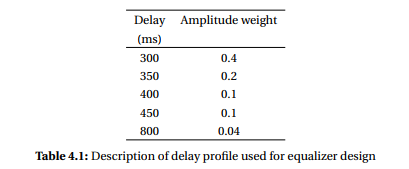

We reuse the AM modulation and carrier frequency from Exercise 1, part II.

## **3.2 Part II: Radio channel impact on AM signal**

Now assume that the sound file from the previous section is amplitude modulated onto a 2.4 GHz carrier frequency $f_c$. The amplitude modulation is obtained as described in equation below. 


$$s_{\text{tx}} =\left(1+m\left(t\right)\right)\cos \left(2\pi f_c \ast t\right)$$


Here, m(t) is the sound signal. The channel characteristics are given in table 4.1.

delay_profile =   [0.3    0.4;
                   0.35   0.2;
                   0.4    0.1;
                   0.45   0.1;
                   0.8    0.04;];
fc = 2.4*10^9;
tc = 1/fc;
fs = 44100;
ts = 1/fs;

The modulation can be rewritten as the following shows


$$S_{\text{tx}} \left(t\right)=\left(1+m\left(t\right)\right)\cos \left(2\pi f_c \ast t\right)=b\left(t\right)\ast \cos \left(2\pi f_c \ast t\right)=\text{Re}\left\lbrace b\left(t\right)\ast e^{j\ast 2\ast \pi \ast f_c \ast t} \right\rbrace$$


Now introducing the delay-profile: 


$$S_{\text{tx}} \left(t-\tau_n \right)=b\left(t-\tau_n \right)\ast e^{j\ast 2\ast \pi \ast f_c \ast \left(t-\tau_n \right)} =b\left(t-\tau_n \right)\ast e^{j\ast 2\ast \pi \ast f_c \ast t} \ast e^{-j\ast 2\ast \pi \ast f_c \ast \tau_n }$$


This shows that the delayprofile's influence on baseband component is independend of the carrier signal. 

Thus the carrier signal can be left out to stay in the base band model


$$S_{{\text{tx}}_{\text{baseband}} } \left(t-\tau_n \right)=\text{Re}\left\lbrace b\left(t-\tau_n \right)\ast e^{-j\ast 2\ast \pi \ast f_c \ast \tau_n } \right\rbrace =b\left(t-\tau_n \right)\ast \cos \left(2\ast \pi \ast f_c \ast \tau_n \right)$$


Where


$$b\left(t-\tau_n \right)=m\left(t-\tau_n \right)+1$$


***e) Determine the channel tranfer function Hc(f) associated with this delay profile. Plot |Hc(f)|.***


$$r\left(t\right)=\sum_{n=1}^{N} \alpha_n \ast s\left(t-\tau_n \right)=\sum_{n=1}^{N} \alpha_n \ast b\left(t-\tau_n \right)\ast \cos \left(2\ast \pi \ast f_c \ast \tau_n \right)$$



$$F\left\lbrace r\left(t\right)\right\rbrace =F\left\lbrace \sum_{n=1}^{N} \alpha_n \ast b\left(t-\tau_n \right)\ast \cos \left(2\ast \pi \ast f_c \ast \tau_n \right)\right\rbrace$$



$$\begin{array}{l}
=\sum_{n=1}^{N} F\left\lbrace \alpha_n \ast b\left(t-\tau_n \right)\ast \cos \left(2\ast \pi \ast f_c \ast \tau_n \right)\right\rbrace \\
=\sum_{n=1}^{N} \alpha_n \ast \cos \left(2\ast \pi \ast f_c \ast \tau_n \right)\ast F\left\lbrace b\left(t-\tau_n \right)\right\rbrace \\
=\sum_{n=1}^{N} \alpha_n \ast \cos \left(2\ast \pi \ast f_c \ast \tau_n \right)\ast e^{-j\ast 2\ast \pi \ast f\ast \tau_n } \ast F\left\lbrace b\left(t\right)\right\rbrace \\
=\left(\sum_{n=1}^{N} \alpha_n \ast \cos \left(2\ast \pi \ast f_c \ast \tau_n \right)\ast e^{-j\ast 2\ast \pi \ast f\ast \tau_n } \right)\ast F\left\lbrace b\left(t\right)\right\rbrace 
\end{array}$$


Thus revieling that the transfer function is


$$H_c \left(f\right)=\sum_{n=1}^{N} \alpha_n \ast \cos \left(2\ast \pi \ast f_c \ast \tau_n \right)\ast e^{-j\ast 2\ast \pi \ast f\ast \tau_n }$$


**Transfer function plot calculated by hand **

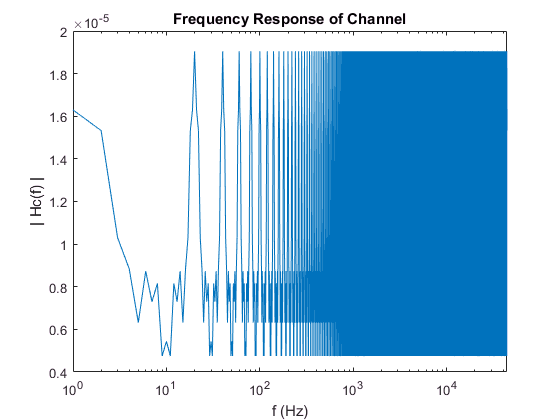

%% Insert summation made in hand 
hc = @(f) sum(delay_profile(:,2).*exp(-1i*2*pi*f.*delay_profile(:,1)).*exp(-1i*2*pi*fc*delay_profile(:,1))); %.*cos(2*pi*fc*delay_profile(:,1)).*exp(-1i*2*pi*f.*delay_profile(:,1))^2)

% Create Frequency Range
f_range = 0:1:44100-1; 

f_response = abs( hc(f_range) / length(f_range) ); % Scale to number of bins
f_phase = angle( hc(f_range) / length(f_range) ); % Scale to number of bins

% Plot Transfer Function
figure(5);
fig5 = semilogx(f_range,f_response);
xlim([f_range(1) f_range(end)]);
title('Frequency Response of Channel')
xlabel('f (Hz)')
ylabel('| Hc(f) |')

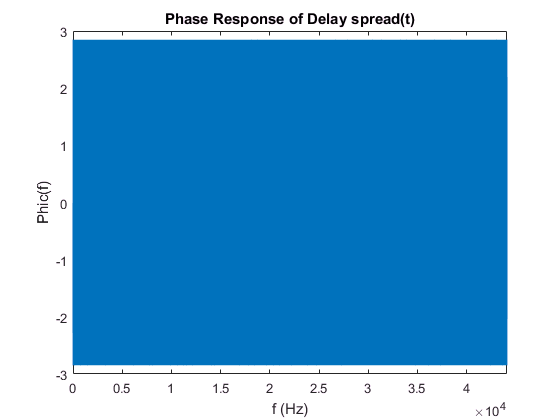


% Plot Transfer Function
figure(6);
fig5 = plot(f_range,f_phase);
xlim([f_range(1) f_range(end)]);
title('Phase Response of Delay spread(t)')
xlabel('f (Hz)')
ylabel('Phic(f)')

## (a) Find the baseband signal at the receiver input by applying the channel effect to the data (wave-file). 

Discuss the effect of the channel by examining the resulting baseband signal.

## (b) Implement a zero-forcing equalizer based on the channel profile. 

Show that this equalizer is working by using it on the AM modulated signal. 

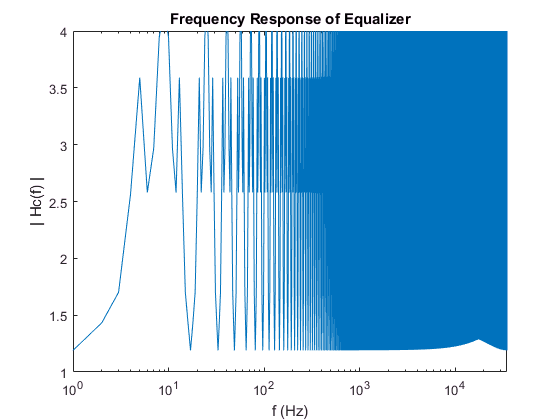

%% Zero Forcing filter
% Create impulse response for delay profile
ts = 1/fs;
time = max(delay_profile(:,1))+ts;
%time = time*3;
%filter_num_tabs = round(time/ts)*2^2;
filter_num_tabs = round(time/ts);

impulse_response = zeros(1,filter_num_tabs);
impulse_response( round(delay_profile(:,1)./ts) + 1 ) = delay_profile(:,2);

%N = 64000;

Hc = fft(impulse_response);
Hc_zf = 1./Hc;
b_coefs = ifft(Hc_zf);
semilogx(abs(Hc_zf))
xlim([0 3.5*10^4])
ylim([1 4])
title('Frequency Response of Equalizer')
xlabel('f (Hz)')
ylabel('| Hc(f) |')

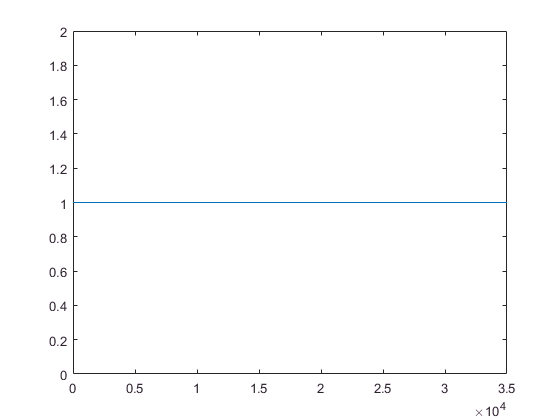

%f_zf_response = abs( hc(f_range) / length(f_range) ); % Scale to number of bins
%stem(impulse_response)
%stem(b_coefs)

%% Filter the Rx signal
%RxFiltered = filter(b_coefs,1,RxSignal);
RxFiltered = filter(b_coefs,1,RxMessage);
%RxFiltered = RxFiltered(filter_num_tabs/2:end-filter_num_tabs/2);

plot(abs(Hc.*Hc_zf))
xlim([0 3.5*10^4])
ylim([0 2])


player_not_filtered = audioplayer(RxMessage,fs);
player_filtered = audioplayer(RxFiltered,fs);

## (c) What happens when you add noise to the channel and use the equalizer on the noisy signal? 

Experiment with different SNR’s. How does this compare to the answer from exercise 1 (part II)? 

**The noise is amplified we hear that**

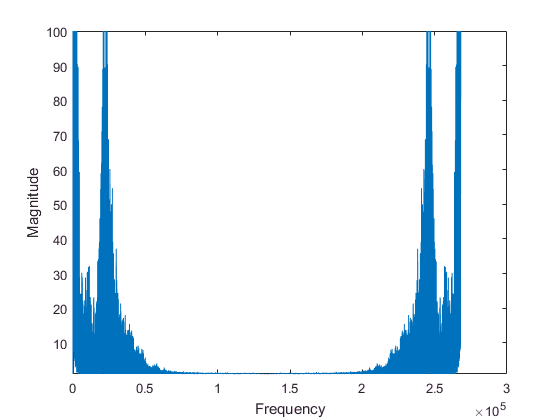

Rx_fft = fft(RxMessage);
Rx_filtered_fft = fft(RxFiltered);

h1 = plot(abs(Rx_fft));
ylim([10^(0) 10^2])
xlabel('Frequency')
ylabel('Magnitude')

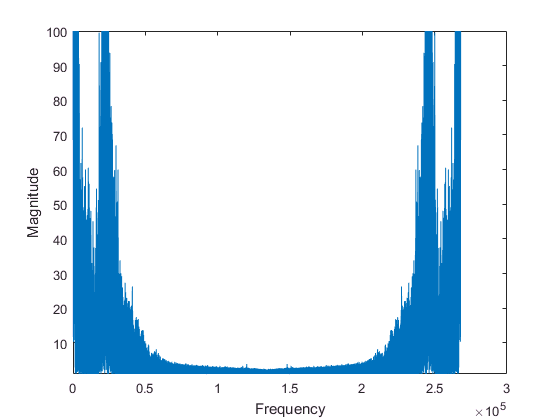

h2 = plot(abs(Rx_filtered_fft));
ylim([10^(0) 10^2])
xlabel('Frequency')
ylabel('Magnitude')

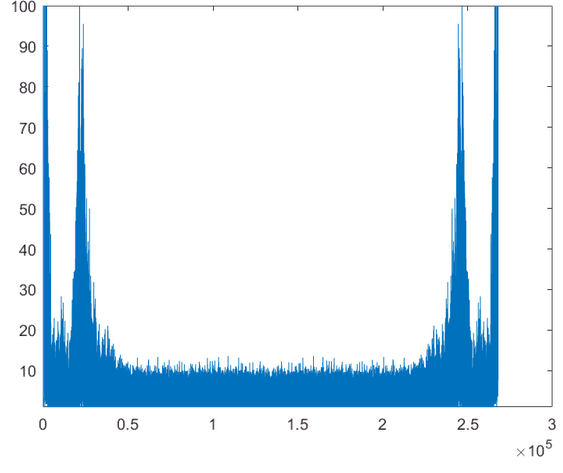

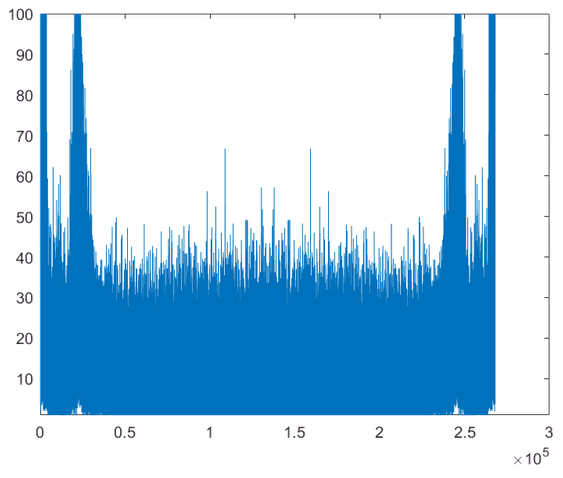

## (d) Try to introduce some minor adjustments to the delay profile. 

Test the equalizer from (b) on data passed through the adjusted channel (note: we do not change the equalizer!). It is ok to take out only a part of the original wav-file, if you experience resource challenges in Matlab..:) 

Delays are introduced or incorectly reduced

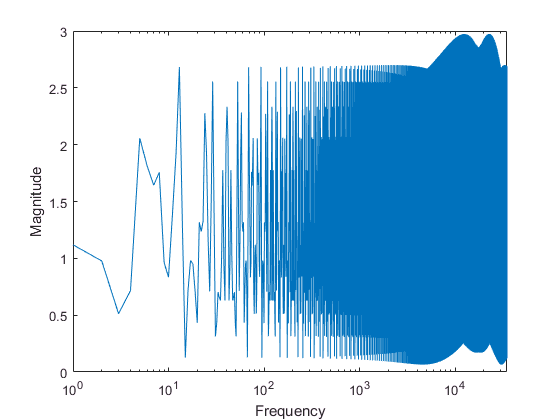


adjusted_delay_profile =   [0.25    0.4;
                            0.39   0.2;
                            0.4    0.15;
                            0.45   0.15;
                            0.7    0.04;];
ts = 1/fs;
time = max(delay_profile(:,1))+ts;
filter_num_tabs = round(time/ts);

impulse_response = zeros(1,filter_num_tabs);
impulse_response( round(adjusted_delay_profile(:,1)./ts) + 1 ) = adjusted_delay_profile(:,2);

Hc_adjusted = fft(impulse_response);


semilogx(abs(Hc_adjusted.*Hc_zf))
xlim([0 3.5*10^4])
xlabel('Frequency')
ylabel('| Hc(f) |')

%plot(phase(Hc_adjusted.*Hc_zf))